### Fig 6

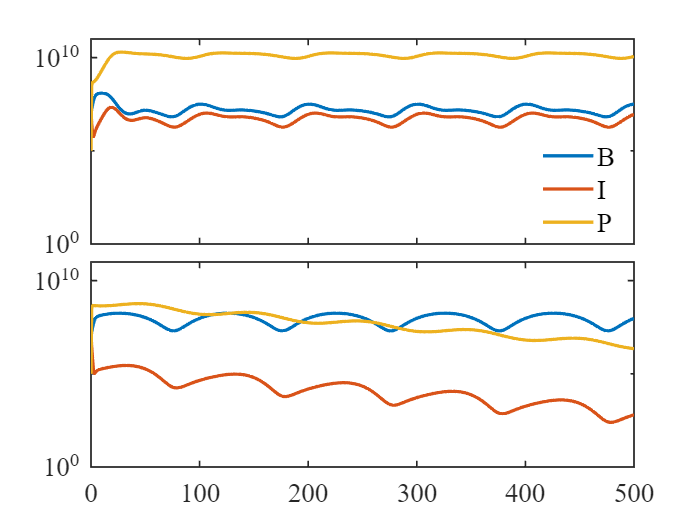

r = 1;  
K = 1;   
a1 = 0.005;   
a2 = 0.0006;
Omega = 50;            
alpha = 2;
delta = 0.04;         
A = 0.8;
f = 0.01;

B0 = 0.1;     
I0 = 0.1;        
P0 = 0.001;     


tspan = [0 500];

y0 = [B0; I0; P0];


options = odeset('NonNegative', [1,2,3], 'RelTol', 1e-12,'MaxStep', 0.01);
[t1, y1] = ode15s(@(t,y) fluctuate_1B_nothre(t, y, A,f,r, K, a1, Omega,alpha, delta), tspan, y0, options);
tout1 = t1;
yout1 = y1*1e8;
yout1(yout1<1)=0;
[t2, y2] = ode15s(@(t,y) fluctuate_1B_nothre(t, y, A,f,r, K, a2, Omega,alpha, delta), tspan, y0, options);
tout2 = t2;
yout2 = y2*1e8;


% ===Visualization ===
FontSize = 16;
figure;


tl = tiledlayout(2, 1, 'TileSpacing', 'tight');

ax1 = nexttile;
semilogy(tout1, yout1(:,1:3), 'LineWidth', 2);

ylim([10^0, 10^11]);
xlim(tspan);

lgd = legend('B','I','P');
lgd.Location = 'best';
lgd.FontSize = FontSize;
lgd.Box = 'off';


ax1.FontName = 'Times New Roman';
ax1.FontSize = FontSize;
ax1.LineWidth = 1;
ax1.XTickLabel = {}; 

ax2 = nexttile;
semilogy(tout2, yout2(:,1:3), 'LineWidth', 2);

ylim([10^0, 10^11]);
xlim(tspan);

ax2.FontName = 'Times New Roman';
ax2.FontSize = FontSize;
ax2.LineWidth = 1;

### Fig 7

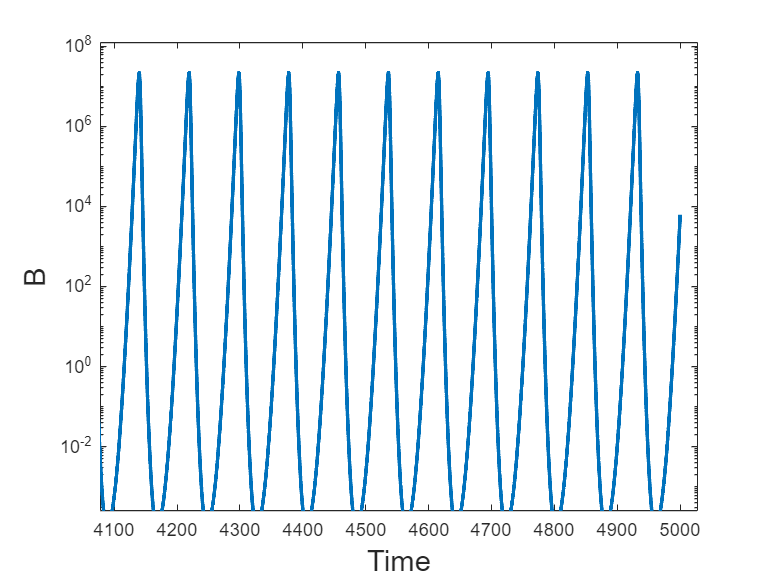

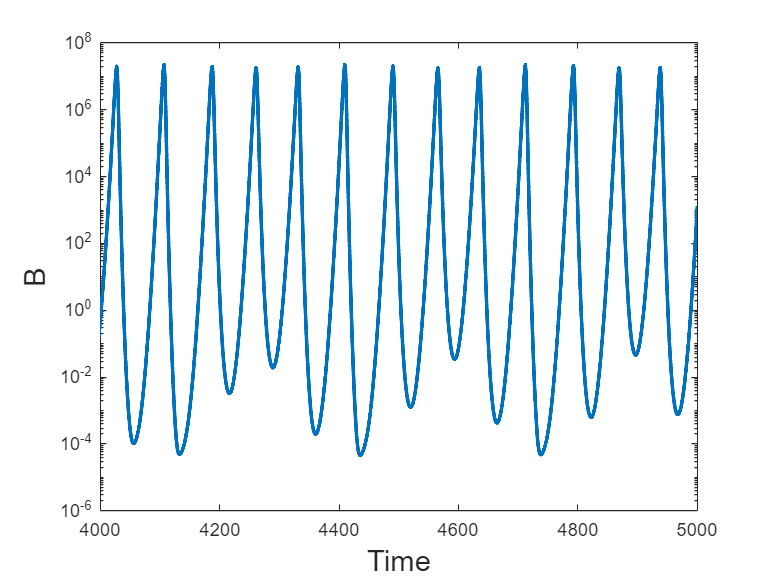

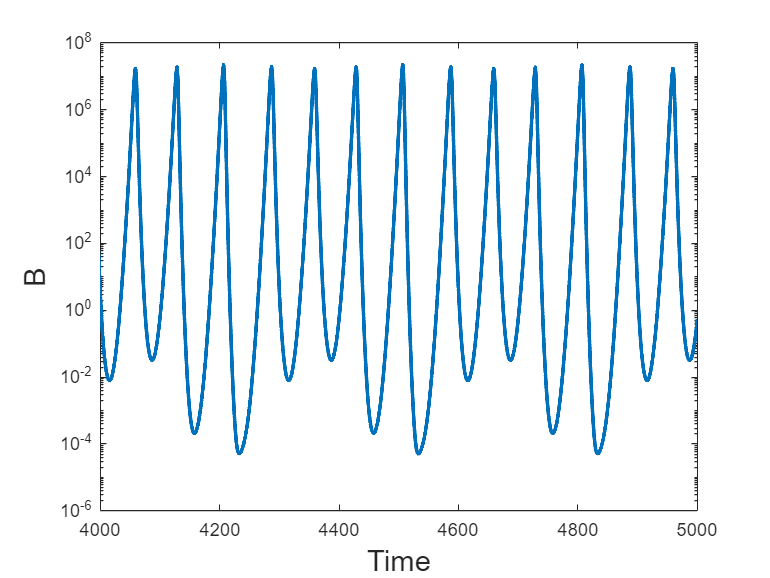

r = 1;   
K = 1;   
a = 0.1;    
Omega = 50;           
alpha = 2;
delta = 0.04;          
A1 = 0.0;               
A2 = 0.35;              
A3 = 0.4;              
f = 0.01;

A_values = [A1, A2, A3];

B0 = 0.1;    
I0 = 0.1;     
P0 = 10;  


tspan = [0 5000];
y0 = [B0; I0; P0];


options = odeset('NonNegative', [1,2,3], 'RelTol', 1e-12,'MaxStep', 0.1);


results = cell(3, 2);
for i = 1:3
    [t, y] = ode15s(@(t,y) fluctuate_1B_nothre(t, y, A_values(i), f, r, K, a, Omega, alpha, delta), tspan, y0, options);
    results{i, 1} = t;
    results{i, 2} = y*1e8;
end

FontSize = 16;


for i = 1:3
    figure;
    semilogy(results{i, 1}, results{i, 2}(:,1), 'LineWidth', 2);
    xlim([4000,5000]);

    ax.FontName = 'Times New Roman';
    ax.FontSize = FontSize;
    ax.LineWidth = 1;
    ylabel('B', 'FontSize', FontSize);    
    xlabel('Time', 'FontSize', FontSize);

end

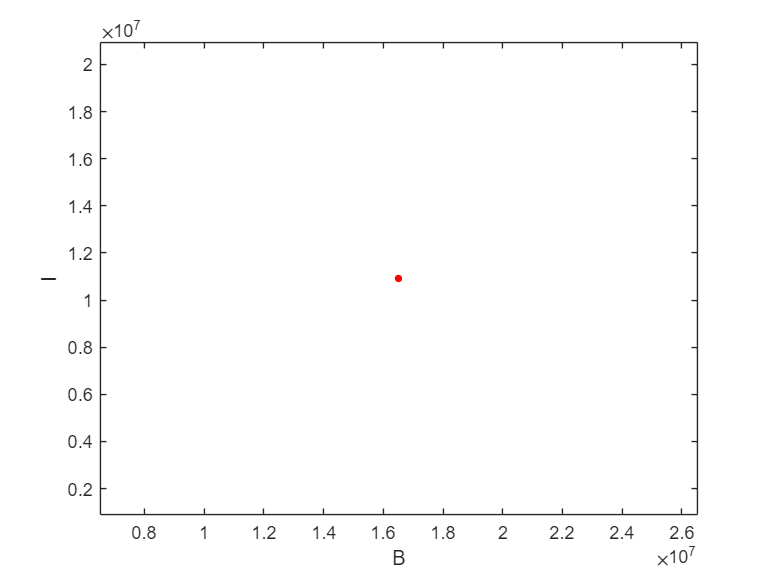

clear; close all;


r = 1;          
K = 1;           
a = 0.1;        
Omega = 50;      
alpha = 2;
delta = 0.04;   


B0 = 0.01;     
I0 = 0.01;    
P0 = 10;        

A = 0;       
f = 0.01;     

tspan = [0 5000];
y0 = [B0; I0; P0];


options = odeset('NonNegative', [1,2,3], 'RelTol', 1e-12, 'MaxStep', 0.1);
[t, y] = ode15s(@(t, y) fluctuate_1B_nothre(t, y, A, f, r, K, a, Omega, alpha, delta), tspan, y0, options);

yout = y*10^8;
tout = t;

idx_start = find(t >= tspan(2)*0.99, 1);
t_plot = tout(idx_start:end);
y_plot = yout(idx_start:end, :);
findpo(y_plot, t_plot, tspan(end));
axis padded;

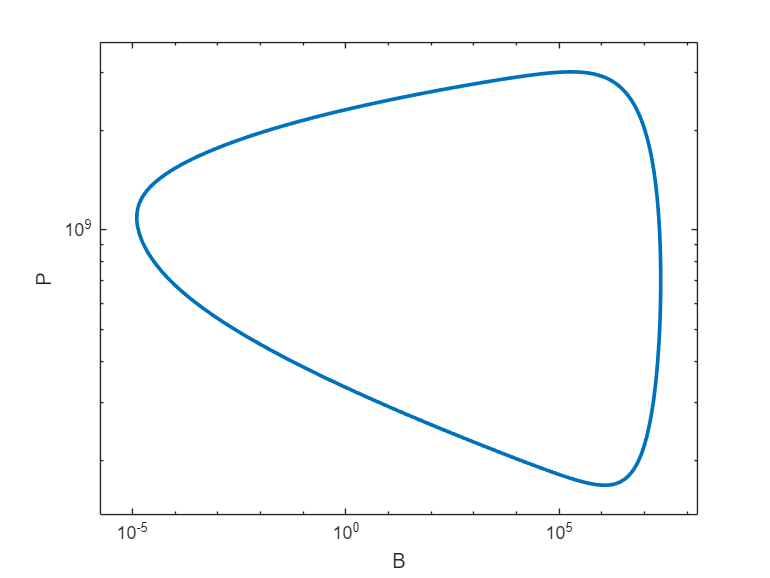

figure;
plot(yout(floor(end*0.95):end,1),yout(floor(end*0.95):end,3), 'LineWidth', 2);
xlabel('B');
ylabel('P');
set(gca,'YScale','log','XScale','log');
axis padded;
grid off;

clear; close all;


r = 1;           
K = 1;          
a = 0.1;        
Omega = 50;     
alpha = 2;
delta = 0.04;   


B0 = 0.1;     
I0 = 0.1;     
P0 = 10;       

A = 0.35;        
f = 0.01;       


tspan = [0 500000];
y0 = [B0; I0; P0];

options = odeset('NonNegative', [1,2,3], 'RelTol', 1e-12, 'MaxStep', 0.01);
[t, y] = ode15s(@(t, y) fluctuate_1B_nothre(t, y, A, f, r, K, a, Omega, alpha, delta), tspan, y0, options);

yout = y*10^8;
tout = t;

idx_start = find(t >= tspan(2)*0.8, 1, 'first');
t_plot = tout(idx_start:end);
y_plot = yout(idx_start:end, :);
findpo(y_plot, t_plot, tspan(end));
axis padded;
figure;
plot(yout(floor(end*0.99):end,1),yout(floor(end*0.99):end,3), 'LineWidth', 2);
xlabel('B');
ylabel('P');
set(gca,'YScale','log','XScale','log');
axis padded;
grid off;

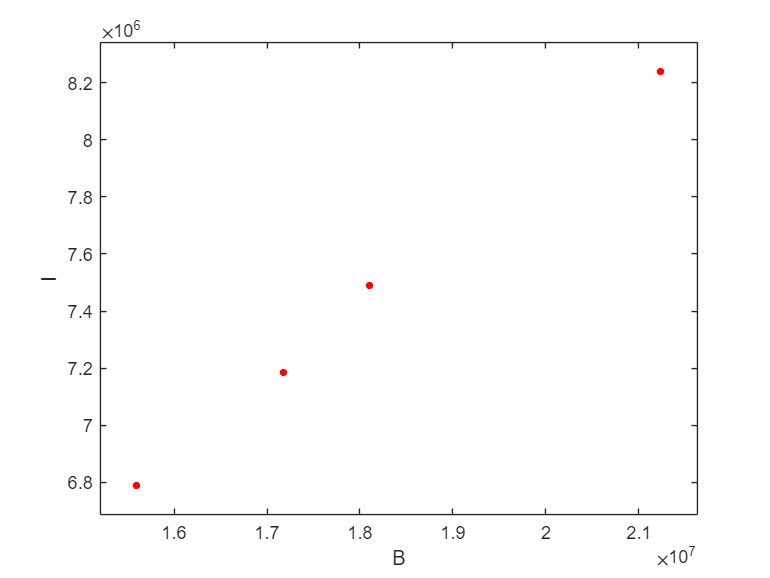

clear; close all;


r = 1;          
K = 1;           
a = 0.1;       
Omega = 50;      
alpha = 2;
delta = 0.04;   


B0 = 0.1;     
I0 = 0.1;      
P0 = 10;        

A = 0.4;       
f = 0.01;       


tspan = [0 50000];
y0 = [B0; I0; P0];

options = odeset('NonNegative', [1,2,3], 'RelTol', 1e-12, 'MaxStep', 0.1);
[t, y] = ode15s(@(t, y) fluctuate_1B_nothre(t, y, A, f, r, K, a, Omega, alpha, delta), tspan, y0, options);


yout = y*10^8;
tout = t;

idx_start = find(t >= tspan(2)*0.9, 1, 'first');
t_plot = tout(idx_start:end);
y_plot = yout(idx_start:end, :);
findpo(y_plot, t_plot, tspan(end));
% xlim([1 4]*10^7);
% ylim([6 12]*10^6);
axis padded;

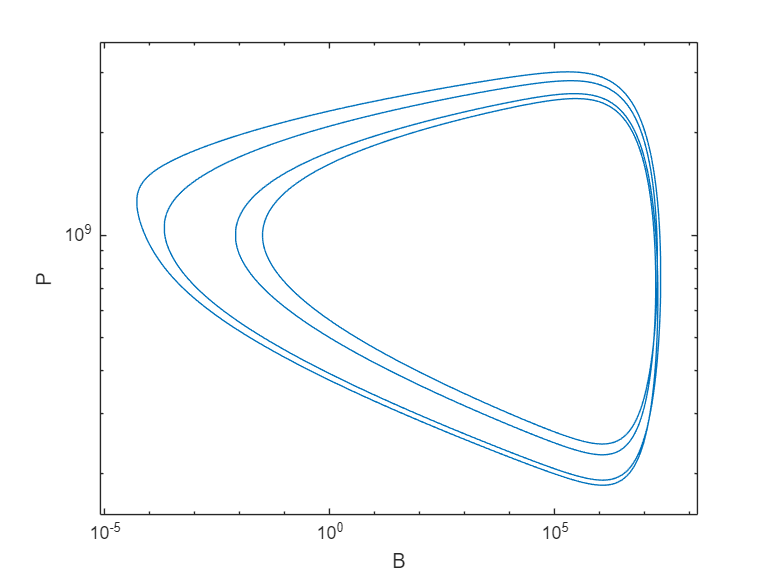

figure;
plot(yout(floor(end*0.9):end,1),yout(floor(end*0.9):end,3));
xlabel('B');
ylabel('P');
set(gca,'YScale','log','XScale','log');
axis padded;
grid off;

### Fig 8

clear;close all;
r = 1;          
a = 0.09;       
Omega = 50;     
alpha = 2;
delta = 0.04;   
K = 1;


B0 = 0.1;
I0 = 0.1;
P0 = 10;
y0 = [B0; I0; P0];

options = odeset('NonNegative', [1,2,3], 'RelTol', 1e-12, 'MaxStep', 0.1);
tspan = [0 5000];



A = 0;
ft = 1;
[t, y] = ode15s(@(t,y) fluctuate_1B_nothre(t,y,A,ft,r,K,a,Omega,alpha,delta), tspan, y0, options);
f0 =PSD_max(y, t,tspan(2));         
f_vec =logspace(log10(f0/1.1),log10(f0*5),300);
A_vec = linspace(0, 0.4, 50);

ratio_matrix = zeros(length(A_vec),length(f_vec));
f_out= zeros(length(A_vec),length(f_vec));
n = length(A_vec);

parfor i =1:length(f_vec)
    i
    f_drive = f_vec(i);
    for l = 1:n
        A = A_vec(l);
        [t, y] = ode15s(@(t,y) fluctuate_1B_nothre(t,y,A,f_drive,r,K,a,Omega,alpha,delta), tspan, y0, options);
        % Calculate the dominant frequency
        f_out(l,i) = PSD_max(y, t,tspan(2));    
        ratio_matrix(l,i) = f_out(l,i)/f_drive;
    end
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).

ans =

     2


ans =

     4


ans =

     6


ans =

     8


ans =

    10


ans =

    12


ans =

    14


ans =

    16


ans =

    15


ans =

     9


ans =

    11


ans =

     3


ans =

     7


ans =

    13


ans =

     1


ans =

     5


ans =

   160


ans =

   106


ans =

   124


ans =

   142


ans =

    52


ans =

    88


ans =

    34


ans =

    70


ans =

   141


ans =

   123


ans =

   105


ans =

   159


ans =

    33


ans =

    87


ans =

    69


ans =

    51


ans =

   140


ans =

   104


ans =

   122


ans =

    32


ans =

    86


ans =

   158


ans =

    68


ans =

    50


ans =

   139


ans =

    31


ans =

   103


ans =

    85


ans =

   121


ans =

   157


ans =

    67


ans =

    49


ans =

   138


ans =

    30


ans =

   102


ans =

   156


ans =

   120


ans =

    84


ans =

    66


a

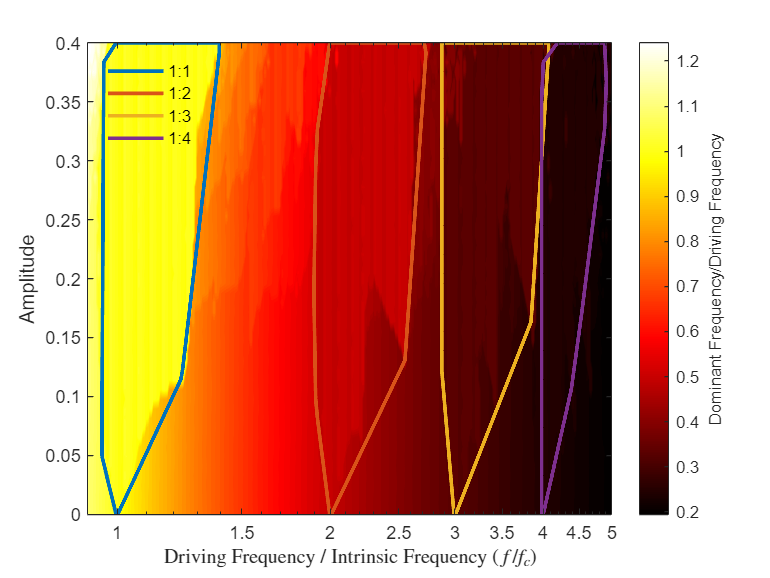

%Visualization
[X, Y] = meshgrid(f_vec./f0, A_vec);
figure;
data = ratio_matrix;

[~, h_contour] = contourf(X, Y, data, 100, 'LineColor', 'auto');
set(h_contour, 'HandleVisibility', 'off'); 
set(gca, 'XScale', 'log')
hold on;
colormap("hot");
hcb = colorbar;
hcb.Label.String = 'Dominant Frequency/Driving Frequency';

n_values = [1, 2, 3, 4];
colors = lines(length(n_values)); 


legend_handles = [];
legend_strings = {};

for i = 1:length(n_values)
    n = n_values(i);
    tol = 0.005 /n;

    condition = abs(data - 1/n) < tol;
    x_points = X(condition);
    y_points = Y(condition);

    if numel(x_points) >= 3
        % convex hull
        k = convhull(x_points, y_points);

        h_plot = plot(x_points(k), y_points(k), 'Color', colors(i,:), 'LineWidth', 2);
        

        legend_handles = [legend_handles, h_plot];
        legend_strings{end+1} = sprintf('1:%d', n);
    end
end

xlabel('Driving Frequency / Intrinsic Frequency $(f / f_c)$', 'Interpreter', 'latex');
ylabel('Amplitude');

lgd = legend(legend_handles, legend_strings, 'Location', 'northwest', 'Box', 'off');

lgd.Color = 'none';        
hold off;